clear all;

allSimTable = readtable("sims/allSims.csv", VariableNamingRule="modify");

allSimTable.OPS = allSimTable.OBP+allSimTable.SLG;
allSimTable.StrikeSwing = allSimTable.Zone_.*allSimTable.Z_Swing_./allSimTable.Swing_;
[t, Idx] = sort(allSimTable.OBP,'descend');
sortedObpTable = allSimTable(Idx,["Year" "Name" "OBP" "MeanSimOBP" "MeanChange"]);
allSimTable = allSimTable(Idx,:);
years = [2002:2019 2021:2023];


obpMeanSimObp = fitlm(allSimTable,'MeanSimOBP~OBP')

obpMeanSimObp = Linear regression model:
    MeanSimOBP ~ 1 + OBP

Estimated Coefficients:
                   Estimate       SE       tStat       pValue   
                   ________    ________    ______    ___________

    (Intercept)     0.37844    0.015444    24.505    2.8668e-121
    OBP            0.046517    0.044658    1.0416        0.29766


Number of observations: 3072, Error degrees of freedom: 3070
Root Mean Squared Error: 0.0858
R-squared: 0.000353,  Adjusted R-Squared: 2.77e-05
F-statistic vs. constant model: 1.09, p-value = 0.298

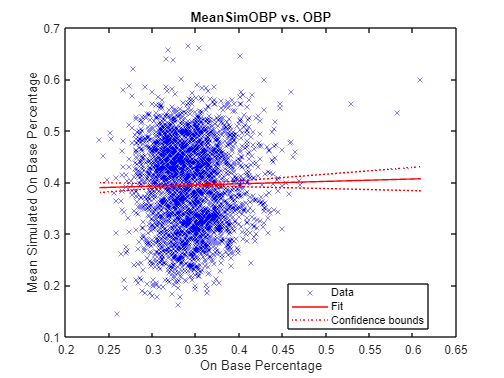

figure(1)
plot(obpMeanSimObp)
xlabel("On Base Percentage");
ylabel("Mean Simulated On Base Percentage");


yearMeanChange = fitlm(allSimTable,'MeanChange~Year')

yearMeanChange = Linear regression model:
    MeanChange ~ 1 + Year

Estimated Coefficients:
                   Estimate        SE         tStat     pValue
                   ________    __________    _______    ______

    (Intercept)     -22.654       0.34411    -65.834      0   
    Year           0.011286    0.00017105     65.981      0   


Number of observations: 3072, Error degrees of freedom: 3070
Root Mean Squared Error: 0.0591
R-squared: 0.586,  Adjusted R-Squared: 0.586
F-statistic vs. constant model: 4.35e+03, p-value = 0

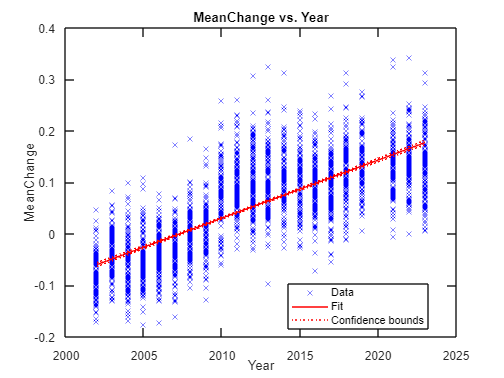

figure(2)
plot(yearMeanChange)

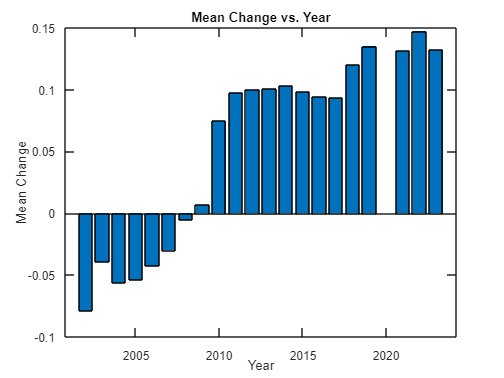

meanDiff = zeros(size(years));
for i=1:size(meanDiff,2)
    weightedSum = sum(allSimTable(allSimTable.Year==years(i),:).MeanChange.*allSimTable(allSimTable.Year==years(i),:).At_Bats);
    totalAtBats = sum(allSimTable(allSimTable.Year==years(i),:).At_Bats);
    meanDiff(i) =  weightedSum/totalAtBats;
end
figure(3)
bar(years,meanDiff)
xlabel('Year');
ylabel('Mean Change');
title('Mean Change vs. Year');

oswingMeanSimOBP = fitlm(allSimTable,'MeanChange~O_Swing_')

oswingMeanSimOBP = Linear regression model:
    MeanChange ~ 1 + O_Swing_

Estimated Coefficients:
                   Estimate       SE         tStat     pValue
                   ________    _________    _______    ______

    (Intercept)    -0.21979    0.0040902    -53.736      0   
    O_Swing_        0.99796     0.014608     68.318      0   


Number of observations: 3072, Error degrees of freedom: 3070
Root Mean Squared Error: 0.0579
R-squared: 0.603,  Adjusted R-Squared: 0.603
F-statistic vs. constant model: 4.67e+03, p-value = 0

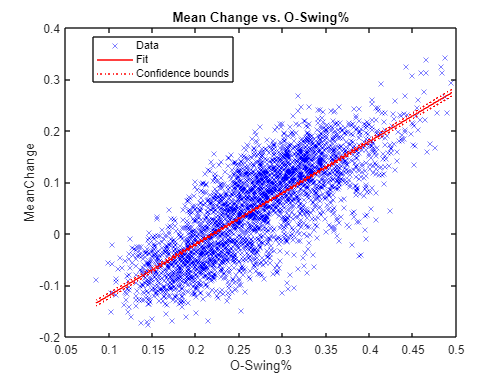

figure(4)
plot(oswingMeanSimOBP)
title('Mean Change vs. O-Swing%')
xlabel('O-Swing%')

yearOswing = fitlm(allSimTable,'O_Swing_~Year')

yearOswing = Linear regression model:
    O_Swing_ ~ 1 + Year

Estimated Coefficients:
                   Estimate         SE         tStat       pValue   
                   _________    __________    _______    ___________

    (Intercept)      -13.301        0.3368    -39.492    3.4961e-276
    Year           0.0067459    0.00016741     40.296    2.3134e-285


Number of observations: 3072, Error degrees of freedom: 3070
Root Mean Squared Error: 0.0579
R-squared: 0.346,  Adjusted R-Squared: 0.346
F-statistic vs. constant model: 1.62e+03, p-value = 2.31e-285

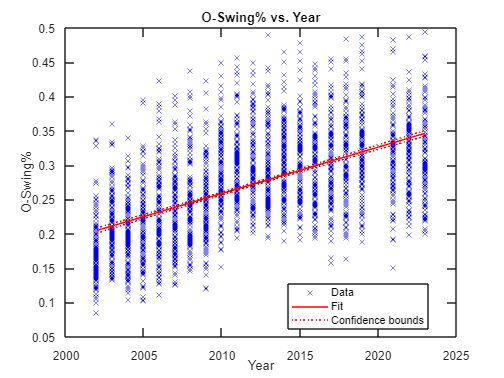

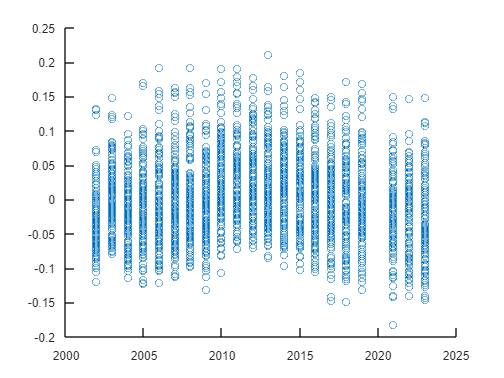

figure(5)
plot(yearOswing)
title('O-Swing% vs. Year')
ylabel('O-Swing%')

strikeSwingMeanChange = fitlm(allSimTable, 'MeanChange ~ StrikeSwing')

strikeSwingMeanChange = Linear regression model:
    MeanChange ~ 1 + StrikeSwing

Estimated Coefficients:
                   Estimate       SE         tStat     pValue
                   ________    _________    _______    ______

    (Intercept)    0.74284     0.0053388     139.14      0   
    StrikeSwing    -1.0125     0.0077488    -130.67      0   


Number of observations: 3072, Error degrees of freedom: 3070
Root Mean Squared Error: 0.0359
R-squared: 0.848,  Adjusted R-Squared: 0.848
F-statistic vs. constant model: 1.71e+04, p-value = 0

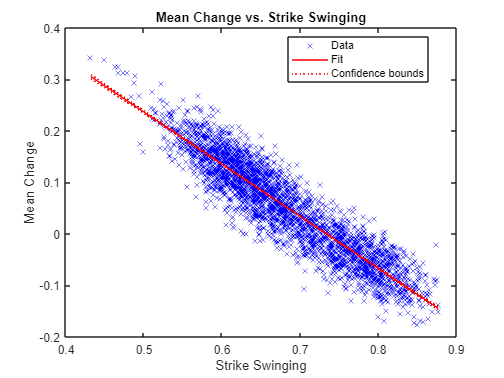

plot(strikeSwingMeanChange)
title('Mean Change vs. Strike Swinging')
xlabel('Strike Swinging')
ylabel('Mean Change')



[t, strSwIdx] = sort(allSimTable.StrikeSwing);
strSwSubset = allSimTable([strSwIdx([1:5 end-4:end])], ["Year" "Name" "MeanChange" "StrikeSwing"])

strSwSubset = 10×4 table
    Year           Name           MeanChange    StrikeSwing
    ____    __________________    __________    ___________

    2022    {'Javier Baez'   }      0.34287       0.43218  
    2021    {'Javier Baez'   }       0.3382       0.44968  
    2021    {'Salvador Perez'}      0.32476       0.46365  
    2013    {'Pablo Sandoval'}      0.32411       0.46733  
    2018    {'Salvador Perez'}      0.31405       0.46783  
    2004    {'Milton Bradley'}    -0.091881       0.87354  
    2004    {'Chipper Jones' }    -0.020392       0.87509  
    2002    {'John Olerud'   }    -0.088966       0.87629  
    2002    {'Jason Kendall' }     -0.15164       0.87678  
    2002    {'Rafael Furcal' }     -0.13828        0.8771  


meanSim = 0.599022690437601

meanSim = 0.5990

stdDevSim = 0.0143959694117068

stdDevSim = 0.0144

zStat = (0.608-meanSim)/stdDevSim

zStat = 0.6236

pValue = 1-normcdf(zStat,0,1)

pValue = 0.2664